# Monte Carlo Simulation to price European Options

This code will be used to price an European Call Option using Monte Carlo Simulations. 

## European Call Option

The European Call Option give the holder the option to buy an asset for a strike price K at time T. If asset S is valued greater than the strike price K the holder will buy the asset at price K and make a profit of S-K. If the asset is valued less than K then the holder will not go through with the trade. Therefor the value of the European Call Option is max(S-K,0) at time T. 

But what is it worth at time 0? That is the question we will answer.

## Monte Carlo

Since the European Call Option depends on a stochastic asset S, Monte Carlo Simulations is used to calculate the fair price by taking the expected value over multiple runs.

## Euler Forward

We will primarly use Euler Forward to time step. Additional information can be found at: [https://en.wikipedia.org/wiki/Euler_method](https://en.wikipedia.org/wiki/Euler_method)

We will also use Melstein method which information can be found at: 

https://en.wikipedia.org/wiki/Milstein_method

## Compute Option Price

S0 = 14;
K = 15;
r = 0.1;
sigma = 0.25;
T = 0.5;
gamma = 1;

delta_t = 0.001;
N = 1e6;

disp(['Estimated price: ', num2str(eu_call_price(S0, K, T, r, sigma, gamma, N, delta_t))])

Estimated price: 0.86596


This is the estimated price using Monte Carlo Simulations. However, for gamma = 1 we have an analytical solution that we can use as the true price. 

disp(['Exact price: ', num2str(bsexact(sigma,r,K,T,S0))])

Exact price: 0.86701


It seems like the Monte Carlo Simulation can calculate the price fairly well. The error comes from the time step delta_t and the amount of samples N. How close do we get to the actual price when we increase N or decrease delta_t?

This we can figure out by doing a convergence check. Theoretically Monte Carlo will have a convergence rate of -1/2 and Euler will have a weak convergence of -1. Is this something we can see?

## Convergence N

Let's start by increasing the number of samples in the Monte Carlo Simulation. To do this we lock the time step delta_t to be 0.01. We do this to not let the time step be of influence. 

rng(0) % random seed
N_vec = floor(logspace(1,6,1e2));
error_vec = zeros(length(N_vec),1);
true_price = bsexact(sigma, r, K, T, S0);

delta_t = 0.01;

for i = 1:length(N_vec)
    n = N_vec(i); % Increase N in each iteration
    error_vec(i) = abs(true_price - eu_call_price(S0,K,T,r,sigma,gamma,n,delta_t)); % Absolute error
end

and then plot it

figure(1), clf
loglog(N_vec, error_vec,'b*'), hold on

### Slope of the error convergence

The slope of the error convergence is the value of the convergence which can be calulated by taking the log. 

pfit = polyfit(log10(N_vec), log10(error_vec), 1);
pval = polyval(pfit, log10(N_vec));
plot(N_vec, 10.^(pval), 'b-')

The slope is the second value in the array

disp(['slope: ', num2str(pfit(1))])

slope: -0.52329


We know that the theoretical convergence rate is -0.5, or $1/\sqrt{N}$ We add this line to the plot for comparison.

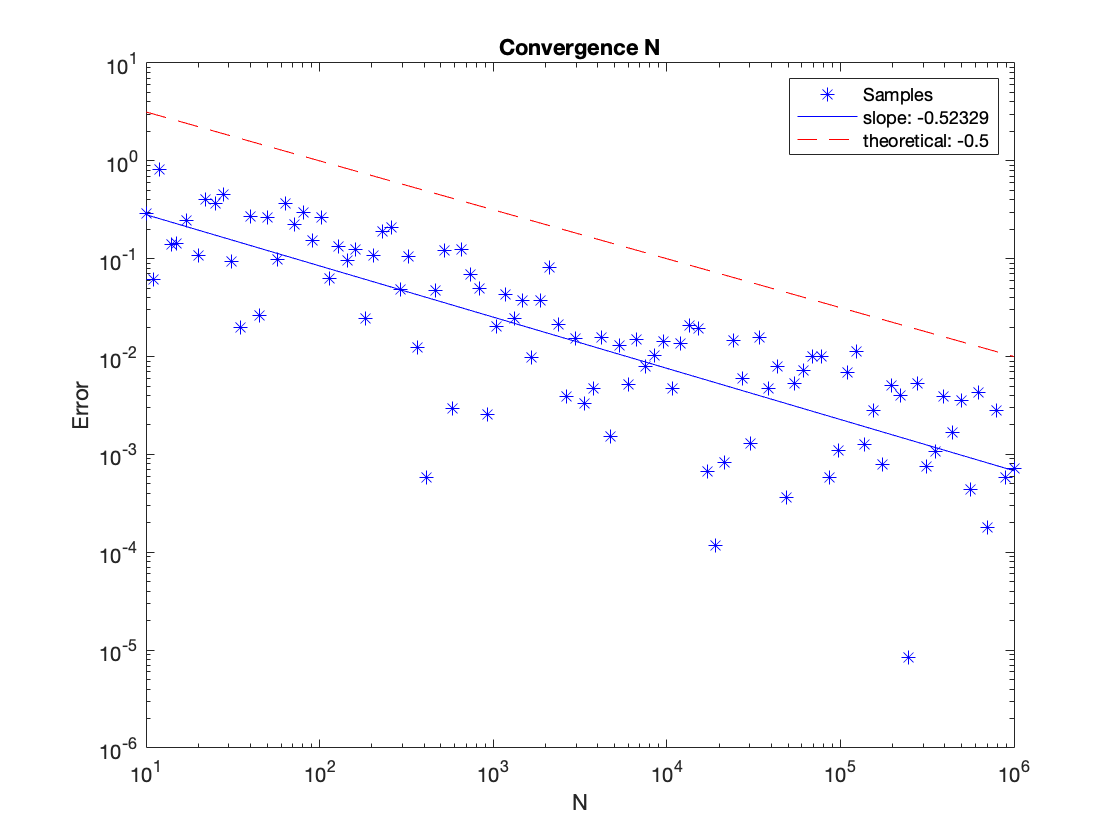

loglog(N_vec, 10 * 1./sqrt(N_vec), '--r')
legend({'Samples',['slope: ' num2str(pfit(1))],'theoretical: -0.5'})
title('Convergence N')
xlabel('N')
ylabel('Error')

hold off

Now we want to see if we can reduce the variance by using an Antithetic method. It works by forcing the paths to be completely negativly correlated.

[price1, stdev1, dist1] = eu_call_price(S0,K,T,r,sigma,gamma,N,delta_t);
[price2, stdev2, dist2] = Antithetic_eu_call(S0,K,T,r,sigma,gamma,N,delta_t);
price3 = bsexact(sigma,r,K,T,S0);

disp(['Estimated price: ', num2str(price1)])

Estimated price: 0.86422


disp(['Estimated antithetic price: ', num2str(price2)])

Estimated antithetic price: 0.86441


disp(['Exact price: ', num2str(price3)])

Exact price: 0.86701


disp(['stdev without antithetic: ', num2str(stdev1)])

stdev without antithetic: 1.5119


disp(['stdev with antithetic: ', num2str(stdev2)])

stdev with antithetic: 0.87701


We can see that the standard deviation reduces when we use antithetics.

DONT REALLY KNOW WHAT TYPE OF PLOT THEY EXPECT HERE.

## Convergence delta_t

Let's start by decreasing the time step delta_t in the Euler stepping. To do this we lock the sample size N. We do this to not let the sample size be of influence and must therefor have it quite high. 

N = 1e6;

delta_t_vec = T./floor(logspace(1,2,100));
error_vec = zeros(length(delta_t_vec),1);
true_price = bsexact(sigma,r,K,T,S0);

for i=1:length(delta_t_vec)
    delta_t = delta_t_vec(i);
    error_vec(i) = abs(true_price - eu_call_price_matrix(S0,K,T,r,sigma,gamma,N,delta_t));
end

and then plot it

figure(3), clf
loglog(delta_t_vec, error_vec,'b*'), hold on

pfit = polyfit(log10(delta_t_vec), log10(error_vec), 1);
pval = polyval(pfit, log10(delta_t_vec));
plot(delta_t_vec, 10.^(pval), 'b-')

disp(['slope: ', num2str(pfit(1))])

slope: 1.0185


We know that the theoretical convergence rate is 1, or delta_t_vec. We add this line to the plot for comparison.

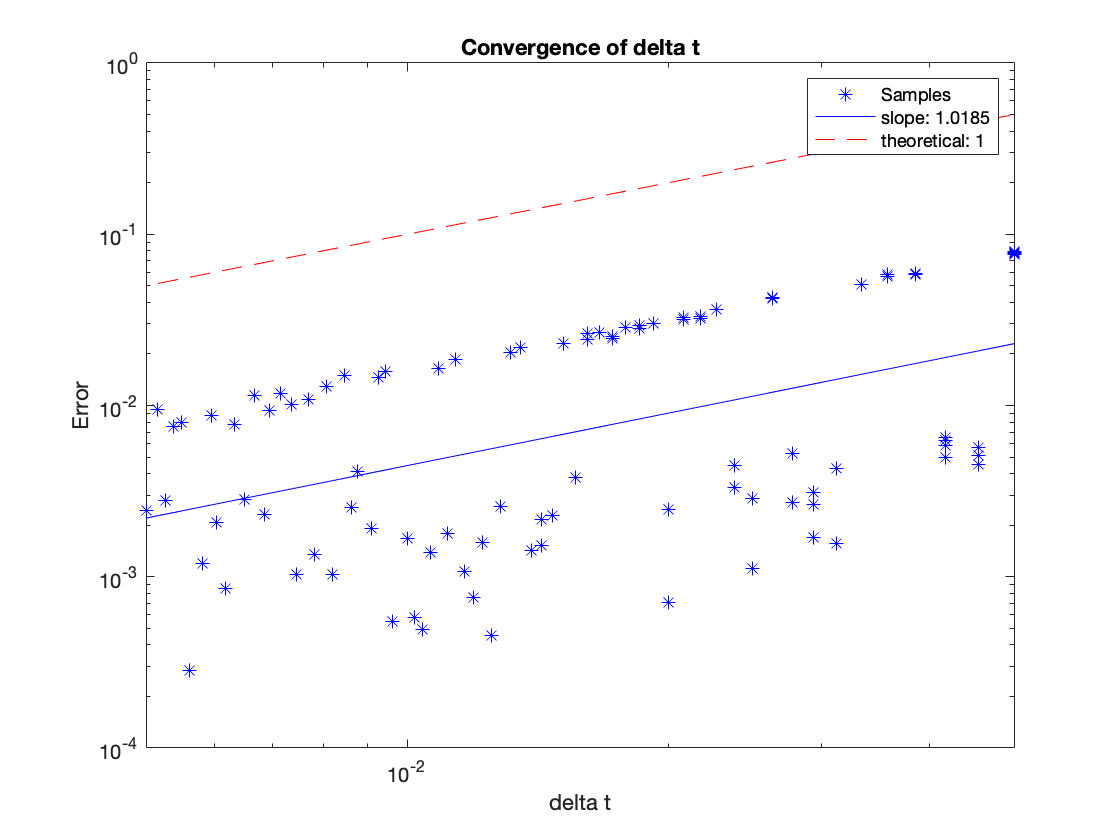

loglog(delta_t_vec, 10 * (delta_t_vec), '--r')
legend({'Samples',['slope: ' num2str(pfit(1))],'theoretical: 1'})
title('Convergence of delta t')
xlabel('delta t')
ylabel('Error')
hold off

We can try to reduce the bias by using another scheme than Euler. We can use Milsten Scheme which have the same order of weak convergence but a better string convergence. However, Millstein require us to know the first derivative of the volatility function. The volatility function in our case is sigma*S^gamma, so therefor the first derivative should be sigma*gamma*(S^(gamma-1)).

[price1, stdev1] = eu_call_price(S0,K,T,r,sigma,gamma,N,delta_t);
[price2, stdev2] = Milstein_eu_call(S0,K,T,r,sigma,gamma,N,delta_t);
price3 = bsexact(sigma,r,K,T,S0);

disp(['Estimated price: ', num2str(price1)])

Estimated price: 0.86603


disp(['Estimated Milstein price: ', num2str(price2)])

Estimated Milstein price: 0.8662


disp(['Exact price: ', num2str(price3)])

Exact price: 0.86701


Let's see what the convergence rate are for Milstein for delta_t:

error_vec = zeros(length(delta_t_vec),1);
true_price = bsexact(sigma,r,K,T,S0);

for i=1:length(delta_t_vec)
    delta_t=delta_t_vec(i);
    error_vec(i) = abs(true_price - Milstein_eu_call_matrix(S0,K,T,r,sigma,gamma,N,delta_t));
end

and then plot it

figure(4), clf
loglog(delta_t_vec, error_vec,'b*'), hold on

pfit = polyfit(log10(delta_t_vec), log10(error_vec), 1);
pval = polyval(pfit, log10(delta_t_vec));
plot(delta_t_vec, 10.^(pval), 'b-')

disp(['slope: ', num2str(pfit(1))])

slope: 0.89118


We know that the theoretical convergence rate is also 1, or delta_t_vec. We add this line to the plot for comparison.

One thing to note is that Milstein has a better strong convergence than Euler. Euler has 1/2 and Milstein has 1.

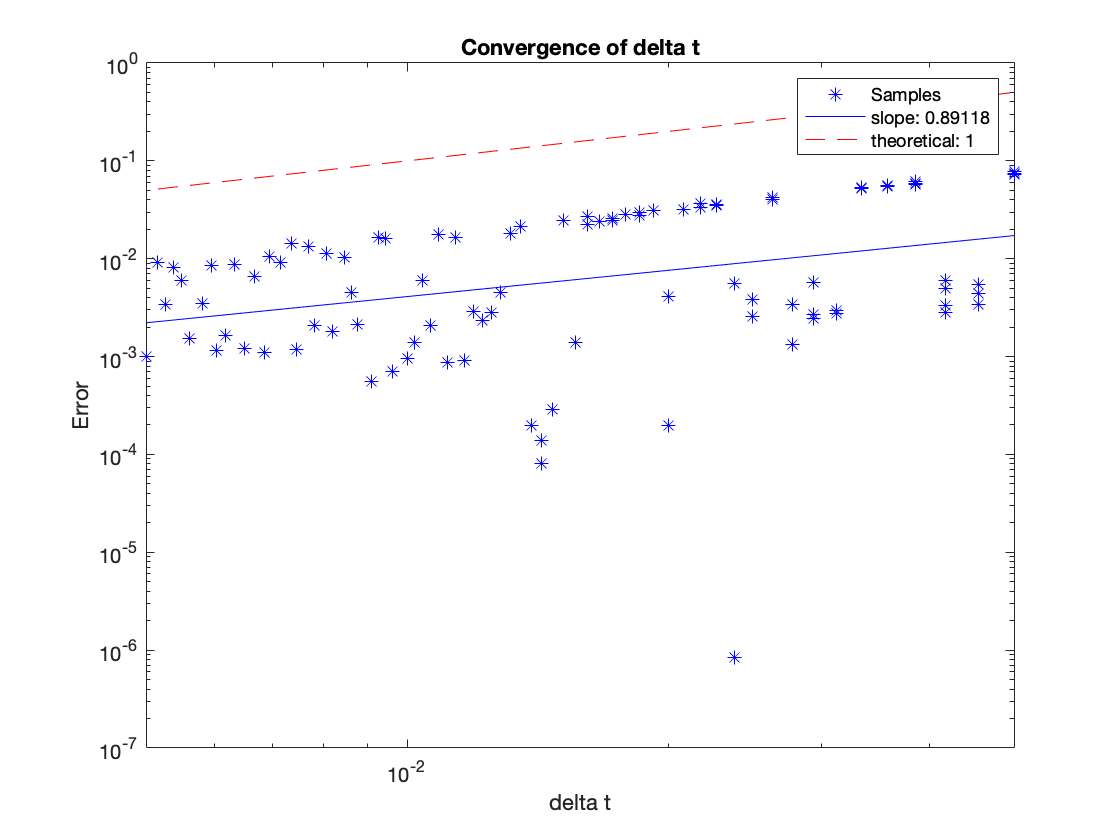

loglog(delta_t_vec, 10*(delta_t_vec), '--r')
legend({'Samples',['slope: ' num2str(pfit(1))],'theoretical: 1'})
title('Convergence of delta t')
xlabel('delta t')
ylabel('Error')
hold off

# Option price depending on gamma:

How does the value of the option change depending on gamma?

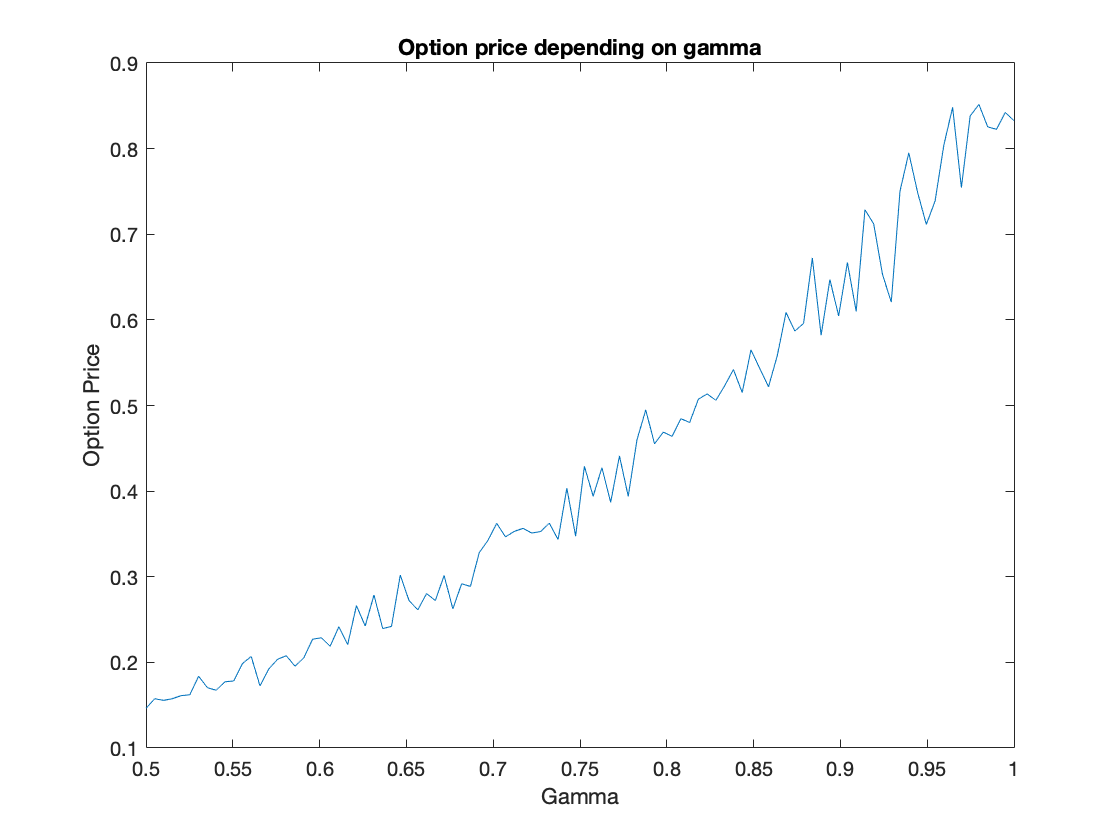

gamma_vector = linspace(0.5, 1, 100);
price_vector = zeros(1, length(gamma_vector));
N = 1000;
delta_t = 0.001;
for i = 1:length(gamma_vector)
    gamma = gamma_vector(i);
    price_vector(i) = eu_call_price(S0,K,T,r,sigma,gamma,N,delta_t);
end

plot(gamma_vector,price_vector);
title('Option price depending on gamma')
xlabel('Gamma')
ylabel('Option Price')

# Appendix - eu_call_price(S0,K,T,r,sigma,gamma,N,delta_t)

function [value_at_time_zero, stdev, distribution] = eu_call_price(S0,K,T,r,sigma,gamma,N,delta_t)
    %Define the value vector
    value_vector = zeros(1,N);
    for i = 1:N
        %make the Euler loop:
        S = S0;
        for j = 1:(T/delta_t)
            S = S + r*S*delta_t + sigma*(S^gamma)*randn*sqrt(delta_t);
        end
        value_vector(i) = max(S-K,0);
    end
    value_at_time_zero = exp(-r*T)*mean(value_vector);
    stdev = std(exp(-r*T)*value_vector);
    distribution = exp(-r*T)*value_vector;
end

On matrix form:

function [value_at_time_zero, stdev] = eu_call_price_matrix(S0,K,T,r,sigma,gamma,N,delta_t)
    %Define the value vector
    S = S0*ones(N,1);
    t = 0;
    while t < T
        t = t + delta_t;
        rand_vector = randn(N,1);
        S = S + r*S*delta_t + sigma*(S.^gamma).*rand_vector*sqrt(delta_t);
    end
    value_vector = max(S-K,0);
    value_at_time_zero = exp(-r*T)*mean(value_vector);
    stdev = std(exp(-r*T)*value_vector);
end

# Appendix - bsexact(sigma, r, E, T, s)

function sol = bsexact(sigma, r, K, T, s)
    d1 = ( log(s/K) + (r + 0.5*sigma^2)*T )/(sigma*sqrt(T));
    d2 = d1 - sigma*sqrt(T);

    F = 0.5*s*(1+erf(d1/sqrt(2))) - exp(-r*T)*K*0.5*(1+erf(d2/sqrt(2)))';

    sol = F;
end


# Appendix - Antithetic_eu_call

function [value_at_time_zero, stdev, distribution] = Antithetic_eu_call(S0,K,T,r,sigma,gamma,N,delta_t)
    %we need to reduce N to half since we calculate 2 each time
    N = floor(N/2);
    value_vector = zeros(1,N);
    for i = 1:(N)
        %make the Euler loop:
        S1 = S0;
        S2 = S0;
        for j= 1:(T/delta_t)
            pos_rand = randn;
            neg_rand = -pos_rand;
            S1 = S1 + r*S1*delta_t + sigma*(S1^gamma)*pos_rand*sqrt(delta_t);
            S2 = S2 + r*S2*delta_t + sigma*(S2^gamma)*neg_rand*sqrt(delta_t);
        end
        value_vector(i) = 0.5*(max(S1-K,0) + max(S2-K,0)); % Antithetic Variate V_AV vector.
    end
    value_at_time_zero = exp(-r*T)*mean(value_vector);
    stdev = std(exp(-r*T)*value_vector);
    distribution = exp(-r*T)*value_vector;
end

# Appendix - Milstein_eu_call

function [value_at_time_zero, stdev] = Milstein_eu_call(S0,K,T,r,sigma,gamma,N,delta_t)
    %Define the value vector
    value_vector = zeros(1,N);
    for i = 1:N
        %make the Euler loop:
        S = S0;
        t = 0;
        for j = 1:(T/delta_t)
            delta_w = sqrt(delta_t)*randn;
            S = S + r*S*delta_t + sigma*(S^gamma)*delta_w + 0.5*(sigma*(S^gamma)*sigma*gamma*(S^(gamma-1))*(delta_w^2 - delta_t));
        end
        value_vector(i) = max(S-K,0);
    end
    value_at_time_zero = exp(-r*T)*mean(value_vector);
    stdev = std(exp(-r*T)*value_vector);
end

Milstein on vector form:

function [value_at_time_zero, stdev] = Milstein_eu_call_matrix(S0,K,T,r,sigma,gamma,N,delta_t)
    %Define the value vector
    S = S0*ones(N,1);
    t = 0;
    while t < T
        t = t + delta_t;
        delta_w = sqrt(delta_t)*randn(N,1);
        S = S + r*S*delta_t + sigma*(S.^gamma).*delta_w + 0.5*(sigma*(S.^gamma)*sigma*gamma.*(S.^(gamma-1)).*((delta_w.^2) - delta_t));
    end
    value_vector = max(S-K,0);
    value_at_time_zero = exp(-r*T)*mean(value_vector);
    stdev = std(exp(-r*T)*value_vector);
end